% MODELLO PREVISIONALE SEDE FISCIANO
clc
clear all
load('workspace.mat')

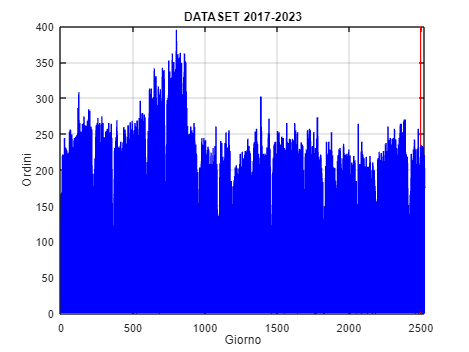

tic

% IMPORT DATI ANNUALI 2017
timeSeries = '2017_2023.xlsx';
[timeSeries, ~] = importdata(timeSeries);
x=linspace(1,length(timeSeries),length(timeSeries))';

%Grafico Serie storica
figure(1)
plot(x,timeSeries,'-b',LineWidth=0.3)
xlim([0 2525])
ylim([0 400])
grid on
xlabel('Giorno')
ylabel('Ordini')
title('DATASET 2017-2023')

% Inizializza diffSeries
diffSeries = diff(timeSeries);

% Test di stazionarietà
[h, ~, ~, ~] = adftest(diffSeries);

% Se la serie non è stazionaria, continua la differenziazione finché lo diventa
while h == 0
    diffSeries = diff(diffSeries);
    [h, ~, ~, ~] = adftest(diffSeries);
end

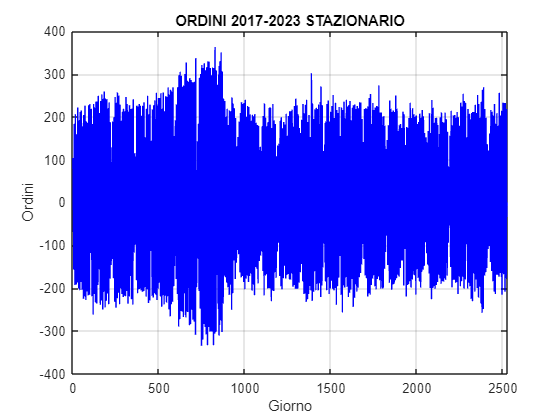


%Esamina la stazionerierà
figure
plot(x([1:end-1]),diffSeries,'-b',LineWidth=0.3);
xlim([0 2525])
ylim([-400 400])
grid on
xlabel('Giorno')
ylabel('Ordini')
title('ORDINI 2017-2023 STAZIONARIO')

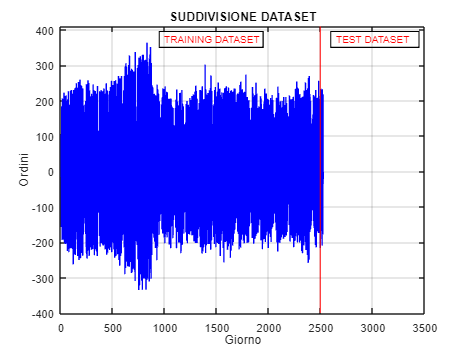

% Esamina la stazionarietà
figure
plot(x([1:end-1]), diffSeries, '-b', 'LineWidth', 0.3);
hold on; % Per mantenere il grafico attuale
xlim([0 3500])
ylim([-400 410])
grid on
xlabel('Giorno')
ylabel('Ordini')
title('SUDDIVISIONE DATASET')

% Aggiungi la linea rossa verticale
x_value = 2495; % Punto x della linea verticale
line([x_value x_value], ylim, 'Color', 'r', 'LineWidth', 1); % Aggiungi la linea rossa verticale

% Aggiungi etichette con rettangolo
text_pos_training = [x_value - 1550, 350, 1000, 45]; % Posizione e dimensioni del rettangolo per "TRAINING DATASET"
text_pos_test = [x_value + 100, 350, 850, 45]; % Posizione e dimensioni del rettangolo per "TEST DATASET"
rectangle('Position', text_pos_training, 'EdgeColor', 'black', 'LineWidth', 1); % Rettangolo per "TRAINING DATASET"
rectangle('Position', text_pos_test, 'EdgeColor', 'black', 'LineWidth', 1); % Rettangolo per "TEST DATASET"
text(x_value - 1500, 375, 'TRAINING DATASET', 'Color', 'red', 'FontSize', 9); % Etichetta "TRAINING DATASET"
text(x_value + 150, 375, 'TEST DATASET', 'Color', 'red', 'FontSize', 9); % Etichetta "TEST DATASET"

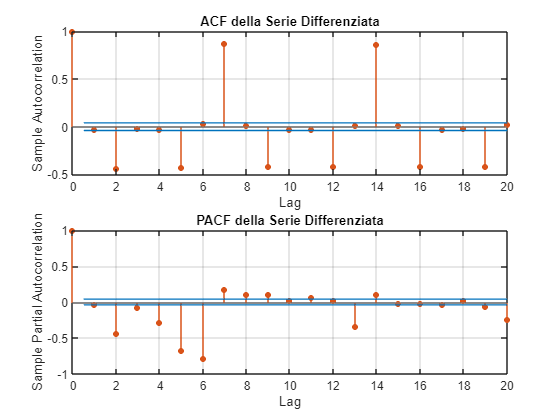



% Osserva i grafici ACF e PACF per guidare la scelta degli ordini ARIMA
figure;
subplot(2,1,1);
autocorr(diffSeries);
title('ACF della Serie Differenziata');

subplot(2,1,2);
parcorr(diffSeries);
title('PACF della Serie Differenziata');

% Inizializzazione delle variabili per il miglior modello SARIMA
bestSARIMAModel = [];
bestRMSE = Inf;
bestOrderNonSeasonal = [];
bestOrderSeasonal = [];

% Dividi la serie temporale in set di addestramento e test
trainingDataSize = 2495;
trainingData = timeSeries(1:trainingDataSize);
testData = timeSeries(trainingDataSize + 1:end);


% Definizione delle griglie dei parametri SARIMA
P_nonSeasonal = 0:3; % Ordine AR non stagionale
D_nonSeasonal = 1;    % Ordine di differenziazione non stagionale
Q_nonSeasonal = 0:3; % Ordine MA non stagionale

P_seasonal = 0:3;     % Ordine AR stagionale
D_seasonal = 1;       % Ordine di differenziazione stagionale
Q_seasonal = 0:3;     % Ordine MA stagionale
S_seasonal = 7;      % Periodo stagionale

% Esplorazione manuale
for p_nonSeasonal = P_nonSeasonal
    for q_nonSeasonal = Q_nonSeasonal
        for p_seasonal = P_seasonal
            for q_seasonal = Q_seasonal
                try
                    % Addestra il modello SARIMA
                    sarimaModel = estimate(arima('ARLags', 1:p_nonSeasonal, 'D', D_nonSeasonal, 'MALags', 1:q_nonSeasonal, ...
                        'SARLags', 1:p_seasonal, 'Seasonality', S_seasonal, 'D', D_seasonal, 'SARLags', 1:q_seasonal), trainingData);

                    % Previsione del modello sui dati di test
                    forecastData = forecast(sarimaModel, numel(testData), 'Y0', trainingData);

                    % Calcola l'RMSE sui dati di test
                    rmseTest = sqrt(mean((forecastData - testData).^2, 'omitnan'));

                    % Aggiorna il miglior modello se necessario
                    if rmseTest < bestRMSE
                        bestRMSE = rmseTest;
                        bestSARIMAModel = sarimaModel;
                        bestOrderNonSeasonal = [p_nonSeasonal, D_nonSeasonal, q_nonSeasonal];
                        bestOrderSeasonal = [p_seasonal, D_seasonal, q_seasonal];
                    end
                catch
                    % Ignora i modelli che non possono essere stimati
                    continue;
                end
            end
        end
    end
end

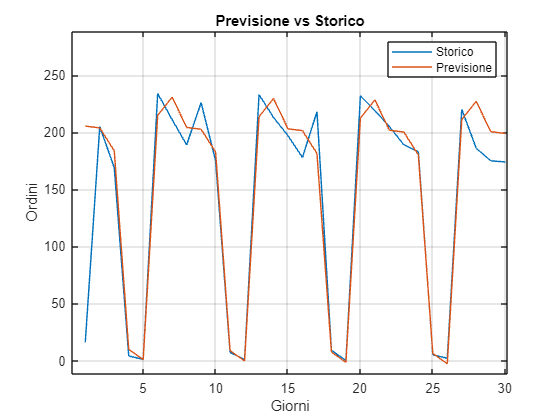


% Visualizzazione grafica delle previsioni rispetto ai dati reali
figure;
plot(testData, 'DisplayName', 'Storico');
hold on;
plot(forecast(bestSARIMAModel, numel(testData), 'Y0', trainingData), 'DisplayName', 'Previsione');
title('Previsione vs Storico');
xlabel('Giorni');
ylabel('Ordini');
legend('show');
grid on;
hold off;


fprintf('Best Non-Seasonal Order: AR(%d) I(%d) MA(%d)\n', bestOrderNonSeasonal(1), bestOrderNonSeasonal(2), bestOrderNonSeasonal(3));

Best Non-Seasonal Order: AR(0) I(1) MA(2)


fprintf('Best Seasonal Order: AR(%d) I(%d) MA(%d)\n', bestOrderSeasonal(1), bestOrderSeasonal(2), bestOrderSeasonal(3));

Best Seasonal Order: AR(0) I(1) MA(0)


fprintf('RMSE on Test Data: %f\n', bestRMSE);

RMSE on Test Data: 38.293132


% Visualizzazione grafica delle previsioni rispetto ai dati reali (2:end)
predicted= forecast(bestSARIMAModel,numel(testData),'Y0', trainingData);

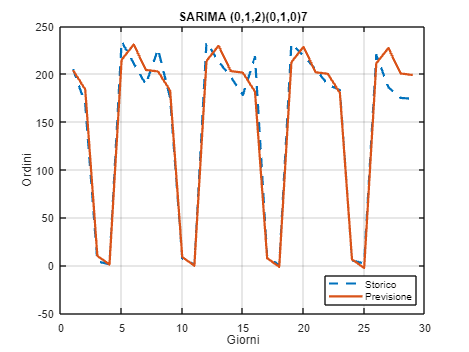

figure;
plot(testData(2:end), 'DisplayName', 'Storico', 'LineWidth', 2, 'LineStyle', '--'); % Linea tratteggiata per lo storico
hold on;
plot(predicted(2:end), 'DisplayName', 'Previsione', 'LineWidth', 2, 'LineStyle', '-'); % Linea continua per la previsione
title('SARIMA (0,1,2)(0,1,0)7');
xlabel('Giorni');
ylabel('Ordini');
legend('show');
lgd = legend('Location', 'southeast'); % Legenda in basso a destra

grid on;
hold off;

% Specifica la directory di destinazione
videoDir = 'C:\Users\Sara\Desktop\grafici\GRAFICI NUOVI\';

% Crea un oggetto VideoWriter
v = VideoWriter(fullfile(videoDir, 'previsione_video.mp4'), 'MPEG-4');
v.FrameRate = 5; % Imposta il numero di frame al secondo

% Apre il video per la scrittura
open(v);

% Numero di giorni nei dati
numDays = numel(testData);

% Crea il plot dello storico
figure;
plot(testData(2:end), 'DisplayName', 'Storico', 'LineWidth', 2, 'LineStyle', '--');
hold on;
title('SARIMA (0,1,2)(0,1,0)7');
xlabel('Giorni');
ylabel('Ordini');
ylim([-50 250]);
grid on;

% Inizializza la previsione come un vettore di NaN con la stessa lunghezza di testData
prediction = NaN(size(testData));

% Aggiungi lo storico al video
frame = getframe(gcf);
writeVideo(v, frame);


% Aggiungi il ritardo tra i frame per la creazione lenta
pause(1); % Ritardo di 1 secondo tra i frame

% Creazione del video delle previsioni
for i = 1:numDays
    % Aggiorna solo la previsione
    prediction(i) = predicted(i);
    
    % Plotta lo storico e la previsione sovrapposti
    plot(testData(2:end), 'DisplayName', 'Storico', 'LineWidth', 2, 'LineStyle', '--');
    hold on;
    plot(prediction(2:end), 'DisplayName', 'Previsione', 'LineWidth', 2);
    title(sprintf('SARIMA (0,1,2)(0,1,0)7 - Giorno %d', i));
    xlabel('Giorni');
    ylabel('Ordini');
    ylim([-50 250]);
    legend('show');
lgd = legend('Location', 'southeast');

    grid on;
    hold off;
    
    % Aggiorna la finestra di figura per visualizzare il nuovo frame
    drawnow;
    
    % Aggiungi il frame al video
    frame = getframe(gcf);
    writeVideo(v, frame);
    
    % Aggiungi il ritardo tra i frame per la creazione lenta
    pause(0.5); % Ritardo di 0.5 secondi tra i frame
end

% Chiudi il video
close(v);


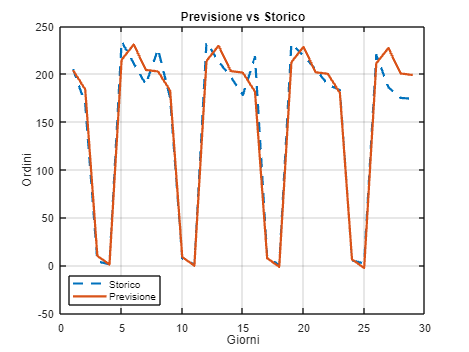

figure;
plot(testData(2:end), 'DisplayName', 'Storico', 'LineWidth', 2, 'LineStyle', '--'); % Linea tratteggiata per lo storico
hold on;
plot(predicted(2:end), 'DisplayName', 'Previsione', 'LineWidth', 2, 'LineStyle', '-'); % Linea continua per la previsione
title('Previsione vs Storico');
xlabel('Giorni');
ylabel('Ordini');
ylim([-50 250]); % Legenda in basso a destra
grid on;
hold off;


% rmseTest = sqrt(mean((forecastData(2:end) - testData(2:end)).^2, 'omitnan'));
 fprintf('RMSE on Test Data: %f\n', rmseTest);

RMSE on Test Data: 22.500310


% Calcolo dell'R-squared escludendo il primo valore
actualValues = testData(2:end); % Considera solo i dati effettivi dalla seconda osservazione in poi
forecastValues = forecast(bestSARIMAModel, numel(testData), 'Y0', trainingData);
forecastValues = forecastValues(2:end);
% Calcola la somma dei quadrati totali
ssTotal = sum((actualValues - mean(actualValues)).^2);
% Calcola la somma dei quadrati residui
ssResidual = sum((actualValues - forecastValues).^2);
% Calcola l'R-squared
rsquared = 1 - (ssResidual / ssTotal);
fprintf('Coefficienti di determinazione (R-squared): %f\n', rsquared);

Coefficienti di determinazione (R-squared): 0.965631


elapsedTime = toc; % Ottieni il tempo trascorso
fprintf('Tempo trascorso: %.4f secondi\n', elapsedTime);

Tempo trascorso: 871.1868 secondi


save('workspace');

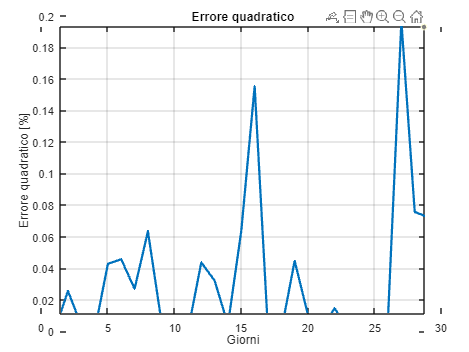

%errore quadratico
tot= sum(testData(2:end).^2);
for i=1:length(testData(2:end))
    err(i)= ((predicted(i+1)-testData(i+1))^2)/tot;
end

err_100=err'*100;

figure;
plot(err_100, 'LineWidth', 2); % Linea più spessa per l'errore quadratico
title('Errore quadratico');
xlabel('Giorni');
ylabel('Errore quadratico [%]');
grid on;

%cumulata dell errore %

num=0;

for i=1:length(testData(2:end));
    num(i)=(predicted(i+1)-testData(i+1))^2;
   
end

a=sum(num);
cum_error=a/tot*100;



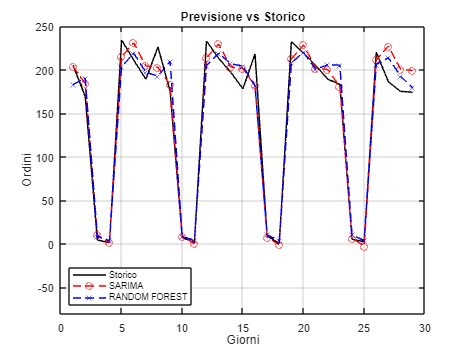

% Visualizzazione grafica delle previsioni rispetto ai dati reali (2:end)
predicted= forecast(bestSARIMAModel,numel(testData),'Y0', trainingData);
random=[212.417176953519
182.895719763747
190.260367511090
8.01211139177250
3.40497770892561
203.254516406672
219.010508910735
196.872934965722
192.583414540412
209.684740001310
8.46714142032010
3.40497770892561
204.726558169229
218.702220808136
206.812383245717
204.002464187191
181.756697603139
10.0743541749040
3.40497770892561
207.792000925285
219.766621623605
200.281348944948
205.592055774725
205.101124528515
10.1457096943845
3.40497770892561
205.736827974409
213.725436899647
192.638879402195
178.907126992218]';

figure;
plot(testData(2:end),'-k' ,'DisplayName', 'Storico');
hold on;
plot(predicted(2:end), '--or','DisplayName', 'SARIMA');
hold on
plot(random(2:end),'--xb', 'DisplayName', 'RANDOM FOREST');
title('Previsione vs Storico');
xlabel('Giorni');
ylabel('Ordini');
legend('show', 'Location', 'southwest', 'FontSize', 8); % Imposta la dimensione della fonte a 8
ylim([-80;250]);
grid on;
hold off; 

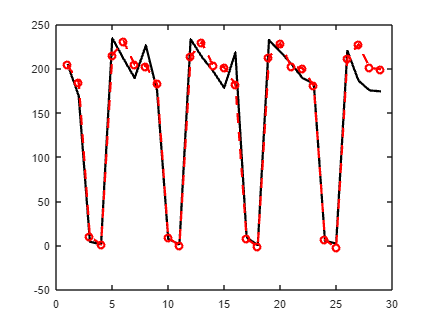

figure;
plot(testData(2:end),'-k' ,'DisplayName', 'Storico', 'LineWidth', 2); % Imposta spessore 2 per la linea
hold on;
plot(predicted(2:end), '--or','DisplayName', 'SARIMA', 'LineWidth', 2); % Imposta spessore 2 per la linea
hold on
plot(random(2:end),'--xb', 'DisplayName', 'RANDOM FOREST', 'LineWidth', 2); % Imposta spessore 2 per la linea
title('Previsione vs Storico');

xlabel('Giorni');

The end operator must be used within an array index expression.

ylabel('Ordini');
legend('show', 'Location', 'southwest', 'FontSize', 8); % Imposta la dimensione della fonte a 8
ylim([-80;250]);
grid on;
hold off; 


% Previsione del modello sui prossimi 30 giorni
forecastData = forecast(bestSARIMAModel, 30, 'Y0', timeSeries);

% Visualizza i risultati
figure;
plot(timeSeries, 'DisplayName', 'Serie Temporale');
hold on;
plot((2526:2555), forecastData, 'DisplayName', 'Previsioni Future');
title('Previsioni Future SARIMA sulla Serie Temporale Completa');
xlabel('Giorno');
ylabel('Ordini');
legend('show');
grid on;
hold off;

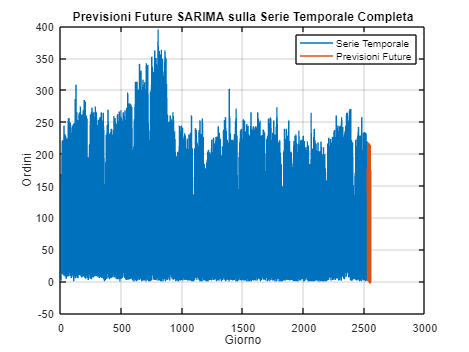

% Previsione dei prossimi giorni
numDaysForecast = 61; % Modifica il numero di giorni previsti come preferisci
futureDates = (1:numDaysForecast) + numel(timeSeries);


% Previsione del modello SARIMA
forecastData = forecast(bestSARIMAModel, numDaysForecast, 'Y0', [trainingData; NaN(numDaysForecast, 1)]);
% Visualizzazione dei risultati con leggenda in basso a sinistra
figure;
plot(x, timeSeries, 'b-', 'LineWidth', 2, 'DisplayName', 'Dati storici validati');
hold on;
plot(futureDates, forecastData, 'r--', 'LineWidth', 2, 'DisplayName', 'Previsione SARIMA');
xlim([2495, 2556]); % Imposta i limiti dell'asse x per mostrare solo la parte di interesse
title('Previsione SARIMA post validazione del modello');
xlabel('Giorni');
ylabel('Valore');
legend('Location', 'southwest'); % Imposta la posizione della leggenda in basso a sinistra
grid on;

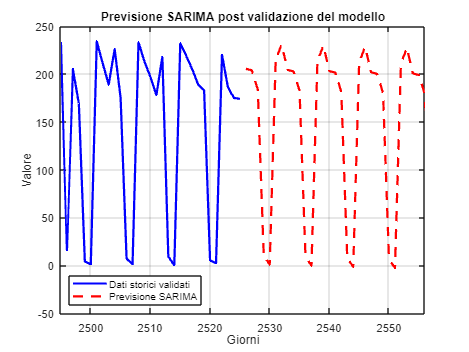


previsione= [198.946878773422
178.930871011237
4.91486324905281

-4.10114451313153
209.882847724684
225.866839962500
199.245926462100
197.669021926932
177.649812612310
3.63060329768902
-5.38860601693219
208.592184668447
224.572975353825
197.948860300989
196.368754213383
176.346343346325
2.32393247926709
-6.69847838779099
207.279110745151
223.256699878093
196.629383272820
195.046075632777
175.020463213282
0.994850793787037
-8.03076162570791
205.943625954797
221.918013535302
195.287495377592
193.700986185113
173.672172213181
-0.356641758751124;]
Giorni= linspace(1,length(previsione),length(previsione))';

figure;
plot(Giorni, previsione, 'b--', 'LineWidth', 2, 'DisplayName', 'Previsione');
hold on;

previsione =   198.9469
  178.9309
    4.9149
   -4.1011
  209.8828
  225.8668
  199.2459
  197.6690
  177.6498
    3.6306


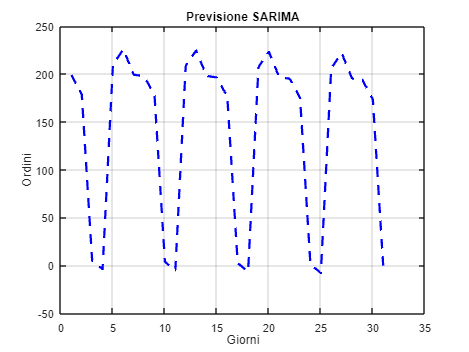

title('Previsione SARIMA');
xlabel('Giorni');
ylabel('Ordini');
grid on;